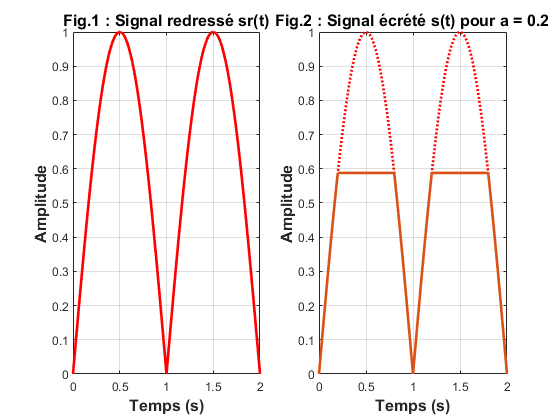

clear; clc; clf; close all;

T=1;
F=1/T;
dt=0.001;
a=0.2;
% Calcul de s(t)
% --------------
[sr,t] = signal_P1718(T, 0.5, dt); % Signal dent de scie
[s,t] = signal_P1718(T, a, dt); % Signal tronqué
%

figure;

subplot(1,2,1);
plot(t,sr,'r','linewidth',2);
grid;
title('\fontsize{12}\bfFig.1 : Signal redressé sr(t)');
xlabel('\fontsize{12}\bfTemps (s)');
ylabel('\fontsize{12}\bfAmplitude');

subplot(1,2,2);
plot(t,sr,':r',t,s,'linewidth',2);
grid;
title(['\fontsize{12}\bfFig.2 : Signal écrété s(t) pour a = ',num2str(a)]);
xlabel('\fontsize{12}\bfTemps (s)');
ylabel('\fontsize{12}\bfAmplitude');






SignalR=mean(s); % Valeur moyenne du signal
Text=['La valeur moyenne sm de s(t) est ',num2str(SignalR)];%num2str(1/length(s) * sum(s))
disp(Text)

La valeur moyenne sm de s(t) est 0.47378



Text=['La Pm de s(t) est ',num2str(0.5*(SignalR)^2)];% 1/length(s) * sum(abs(s).^2)
disp(Text)

La Pm de s(t) est 0.11223


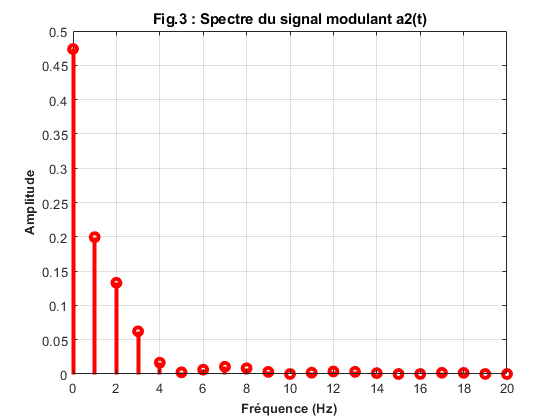

% Spectre en amplitude du signal
Fm=1;
NbHarm=20;
C0=mean(s);
for k=1:NbHarm
    X(k)=mean(s.*exp(-2*pi*1i*k*Fm*t));
    C(k)=abs(2*X(k)); Phi(k)=angle(X(k));
    if C(k)<0.001; C(k)=0;
    end
end
% Tracé du spectre en amplitude du signal s(t)
k=1:NbHarm;
figure(3);
stem(0,C0,'r','LineWidth',3);grid;hold on;
stem(k,C,'r','LineWidth',3);hold off;
title('Fig.3 : Spectre du signal modulant a2(t)')
xlabel('\fontsize{10}\bfFréquence (Hz)');
ylabel('\fontsize{10}\bfAmplitude')


Pm=0.5*(C0)^2

Pm = 0.1122

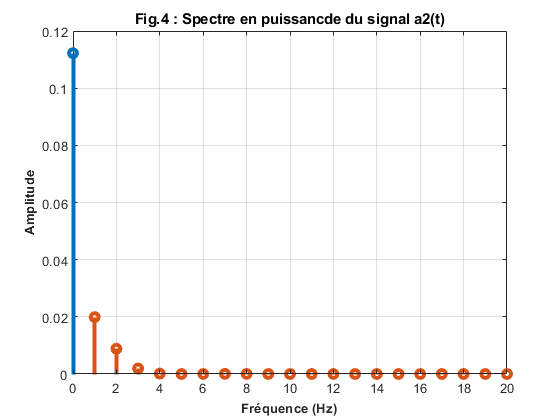

for k=1:NbHarm
    Ph(k)=0.5*C(k)^2;
end
%
k=1:NbHarm;
figure(4);
stem(0,Pm,'LineWidth',3);grid on; hold on;
stem(k,Ph,'LineWidth',3);grid on;hold off;
title('Fig.4 : Spectre en puissancde du signal a2(t)')
xlabel('\fontsize{10}\bfFréquence (Hz)');
ylabel('\fontsize{10}\bfAmplitude')